str = "kulakov";
dis = sprintf("Изначальное сообщение: %s\n", str);
disp(dis);

Изначальное сообщение: kulakov



bit = 7;
x = char(str);
massage = encode(x);
dis = sprintf("Битовая последовательность: \n");
disp(dis);

Битовая последовательность: 



disp(num2str(massage));

1  1  0  1  0  1  1  1  0  1  0  1  1  1  0  0  1  1  0  1  1  1  0  0  0  0  1  1  1  1  0  1  0  1  1  1  1  1  1  0  1  1  0  1  1  0  1  1  1


dis = sprintf("\nБитовая последовательность после шифрования: \n");
disp(dis);


Битовая последовательность после шифрования: 



conv_massage = conv_encode(massage);

disp(num2str(conv_massage));

1  1  0  1  0  1  1  1  0  1  0  1  0  0  0  1  1  1  0  0  0  0  1  0  0  0  0  1  1  1  1  1  0  1  1  1  1  1  0  0  1  0  1  1  0  0  1  1  1  0  1  0  0  1  1  0  1  0  0  1  1  0  1  0  1  1  1  0  0  0  0  1  0  0  1  0  0  0  0  0  0  1  0  0  1  1  0  1  0  1  0  0  0  1  0  1  1  1



ran_index = randperm(length(conv_massage));
dis = sprintf("\nВектор перемежения: \n");
disp(dis);


Вектор перемежения: 



disp(num2str(ran_index));

53  92  84  86   8  25   6  75  43  23  42  22  17  97   5   9  27  59  39   1  24  89  76  41  83  81  64  88  37  16  69  58  33  34  66  65  56  63  31  87  78  51   2  49   3  15  36  11  98  12  82  57  30  55  74  70   7  28  21  79  90  60  61  10  26  38  46  93  68  47  71  85  44  80  35   4  50  29  62  14  94  13  45  32  72  77  18  73  95  91  40  67  20  52  48  19  96  54



interleave_massage = interleave(conv_massage, ran_index);
dis = sprintf("\nБитовая последовательность после перемежения: \n");
disp(dis);


Битовая последовательность после перемежения: 



disp(num2str(interleave_massage));

0  0  0  1  1  0  1  1  1  1  0  0  1  1  0  0  0  0  0  1  0  0  0  1  0  0  0  1  1  1  0  0  0  1  1  1  0  1  1  0  0  1  1  1  0  0  1  0  1  1  1  1  1  1  0  0  1  1  0  0  1  1  1  1  0  1  0  0  0  1  0  1  1  0  1  1  0  1  0  0  1  0  0  1  1  0  1  0  0  0  0  1  0  0  1  0  1  1



qpsk_sequence = qpsk_modulation(interleave_massage); % модуляция qpsk
fprintf('Mодуляция qpsk: ');

Mодуляция qpsk: 

for t = 1:length(qpsk_sequence)
fprintf("%g+%gi\t", real(qpsk_sequence(t)), imag(qpsk_sequence(t)));
if(mod(t, 8) == 0)
    fprintf("\n");
end
end

0.707+0.707i	0.707+-0.707i	-0.707+0.707i	-0.707+-0.707i	-0.707+-0.707i	0.707+0.707i	-0.707+-0.707i	0.707+0.707i	0.707+0.707i	0.707+-0.707i	0.707+0.707i	0.707+-0.707i	0.707+0.707i	0.707+-0.707i	-0.707+-0.707i	0.707+0.707i	0.707+-0.707i	-0.707+-0.707i	0.707+-0.707i	-0.707+0.707i	0.707+-0.707i	-0.707+-0.707i	0.707+0.707i	-0.707+0.707i	-0.707+-0.707i	-0.707+-0.707i	-0.707+-0.707i	0.707+0.707i	-0.707+-0.707i	0.707+0.707i	-0.707+-0.707i	-0.707+-0.707i	0.707+-0.707i	0.707+0.707i	0.707+-0.707i	0.707+-0.707i	-0.707+0.707i	-0.707+-0.707i	0.707+-0.707i	0.707+0.707i	-0.707+0.707i	0.707+-0.707i	-0.707+0.707i	-0.707+0.707i	0.707+0.707i	0.707+-0.707i	0.707+0.707i	-0.707+0.707i	-0.707+-0.707i	

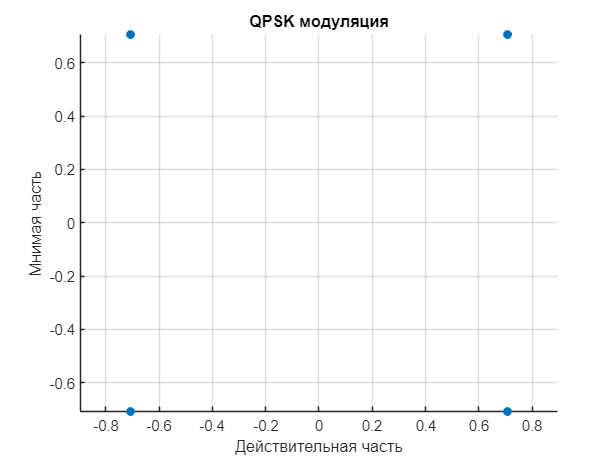

fprintf("\n");
% Отображение QPSK символов на комплексной плоскости
scatter(real(qpsk_sequence), imag(qpsk_sequence), 'filled');
xlabel('Действительная часть');
ylabel('Мнимая часть');
title('QPSK модуляция');
grid on;
axis equal;



ofdm = ofdm_modulation(qpsk_sequence);

disp("OFDM");

OFDM


disp(ofdm);

   0.0808 - 0.0144i  -0.0334 + 0.0590i  -0.0188 - 0.0373i   0.0154 - 0.0059i   0.0169 + 0.0070i  -0.0172 + 0.0226i  -0.0152 - 0.0275i   0.0318 - 0.0043i  -0.0101 + 0.0336i  -0.0247 - 0.0295i   0.0386 + 0.0004i  -0.0228 + 0.0236i  -0.0017 - 0.0205i   0.0047 - 0.0004i   0.0155 + 0.0054i  -0.0248 + 0.0172i   0.0026 - 0.0347i   0.0215 + 0.0189i  -0.0141 + 0.0054i  -0.0059 - 0.0018i   0.0010 - 0.0152i   0.0172 + 0.0086i  -0.0121 + 0.0124i  -0.0096 - 0.0114i   0.0124 - 0.0079i   0.0028 + 0.0122i  -0.0061 - 0.0006i  -0.0037 - 0.0005i   0.0038 - 0.0095i   0.0051 + 0.0114i  -0.0086 - 0.0083i   0.0151 + 0.0100i  -0.0319 + 0.0008i   0.0314 - 0.0347i   0.0064 + 0.0570i  -0.0469 - 0.0356i   0.0501 - 0.0023i  -0.0333 + 0.0162i   0.0312 - 0.0179i  -0.0312 + 0.0355i   0.0074 - 0.0521i   0.0208 + 0.0400i  -0.0238 - 0.0166i   0.0150 + 0.0091i  -0.0138 - 0.0049i   0.0012 - 0.0057i   0.0270 - 0.0103i  -0.0197 + 0.0613i  -0.0472 - 0.0811i   0.1024 + 0.0216i  -0.0736 + 0.0545i   0.0027 - 0.0587i   0.0178 + 


fprintf('Mодуляция ofdm: ');

Mодуляция ofdm: 

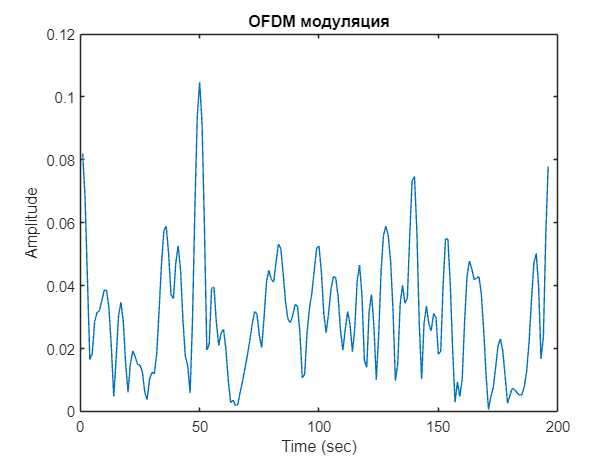

plot(abs(ofdm));
xlabel("Time (sec)");
ylabel("Amplitude");
title("OFDM модуляция");


qpsk_desequence = qpsk_demodulation(qpsk_sequence); % демодуляция qpsk
fprintf("Демодуляция qpsk: ");

Демодуляция qpsk: 

for t = 1:length(qpsk_desequence)
fprintf("%d  ",qpsk_desequence(t));
end

0  0  0  1  1  0  1  1  1  1  0  0  1  1  0  0  0  0  0  1  0  0  0  1  0  0  0  1  1  1  0  0  0  1  1  1  0  1  1  0  0  1  1  1  0  0  1  0  1  1  1  1  1  1  0  0  1  1  0  0  1  1  1  1  0  1  0  0  0  1  0  1  1  0  1  1  0  1  0  0  1  0  0  1  1  0  1  0  0  0  0  1  0  0  1  0  1  1  

fprintf("\n");

deinterleave_massage = deinterleave(interleave_massage, ran_index);
dis = sprintf("\nБитовая последовательность после деперемежения: \n");
disp(dis);


Битовая последовательность после деперемежения: 



disp(num2str(deinterleave_massage));

1  1  0  1  0  1  1  1  0  1  0  1  0  0  0  1  1  1  0  0  0  0  1  0  0  0  0  1  1  1  1  1  0  1  1  1  1  1  0  0  1  0  1  1  0  0  1  1  1  0  1  0  0  1  1  0  1  0  0  1  1  0  1  0  1  1  1  0  0  0  0  1  0  0  1  0  0  0  0  0  0  1  0  0  1  1  0  1  0  1  0  0  0  1  0  1  1  1



dis = sprintf("\nБитовая последовательность после дешифрования: \n");
disp(dis);


Битовая последовательность после дешифрования: 



conv_decode_massage = conv_decode(deinterleave_massage, bit);
disp(num2str(conv_decode_massage));

1  1  0  1  0  1  1  1  0  1  0  1  1  1  0  0  1  1  0  1  1  1  0  0  0  0  1  1  1  1  0  1  0  1  1  1  1  1  1  0  1  1  0  1  1  0  1  1  1


massage_str = decode(conv_decode_massage, bit);
dis = sprintf("\nДекодированное сообщение: %s", massage_str);
disp(dis);


Декодированное сообщение: kulakov
